# Practical Coding and Math, Homework 4

Hannah Quick

17 September, 2024

## Load the data

Download monthly sea level data from Charleston, SC using this PSMSL dataset. You can download it directly or copy and paste it into a .txt file. 	

1. Read in the sea level data, creating separate vectors for the date (first column) and the sea level (second column).

% Read in data
data = readtable("ps4_seaLevel.csv");

% Separate vectors
year_data = data.year

year = 1.0e+03 *

    1.9218
    1.9219
    1.9220
    1.9220
    1.9221
    1.9222
    1.9223
    1.9224
    1.9225
    1.9225


sea_lvl = data.sea_level

sea_lvl =         7033
        6939
        6893
        6768
        6853
        6838
        6832
        6914
        6893
        6838


2. Plot the time series of sea level data 

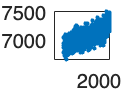

plot(year, sea_lvl, ".-")

3. Fit a linear regression to the whole time series (1921-2023) 

% Calculate the linear regression

year_mat = zeros(length(year),2);
year_mat(:,1) = year;
year_mat(:,2) = 1

year_mat = 1.0e+03 *

    1.9218    0.0010
    1.9219    0.0010
    1.9220    0.0010
    1.9220    0.0010
    1.9221    0.0010
    1.9222    0.0010
    1.9223    0.0010
    1.9224    0.0010
    1.9225    0.0010
    1.9225    0.0010


linfit = year_mat\sea_lvl

linfit =     3.5382
   59.6638


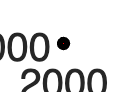


% Fit the linear regression
plot(year,sea_lvl,'k.','markersize',20);hold on
plot(year,linfit(2)+linfit(1).*year,'r-','linewidth',4)
ylabel('Sea level','fontsize',20)
xlabel('year','fontsize',20)
set(gca,'fontsize',20)

4. Calculate the anomalies about the linear regression, and then calcuate the variance about the detrended data. 

% Calculate the anomalies
Linfit_var = linfit(2)+linfit(1).*year;

anomalies = Linfit_var-sea_lvl;

% Calculate the variance
anomalies_variance = anomalies'*anomalies / (length(anomalies)-1)

anomalies_variance = 1.0567e+04

% Using variance calculation for a sample


5. Calcuate sea level rise rates for each of these periods: 1923-1942, 1943-1962, 1963-1982, 1983-2002, 2003-2022.  	

period = [1923, 1942];
time_index = year_data>=period(1) & year_data<=period(2);
time_slice = year_data(time_index);
sea_slice = sea_lvl(time_index);
year_mat = zeros(length(time_slice),2);
year_mat(:,1) = time_slice;
year_mat(:,2) = 1;
linfit = year_mat\sea_slice;

rate_23_42 = linfit(1)

rate_23_42 = 3.5845



period = [1943, 1962];
time_index = year>=period(1) & year<=period(2);
time_slice = year(time_index);
sea_slice = sea_lvl(time_index);
year_mat = zeros(length(time_slice),2);
year_mat(:,1) = time_slice;
year_mat(:,2) = 1;
linfit = year_mat\sea_slice;

rate_43_62 = linfit(1)

rate_43_62 = 1.1417


period = [1963, 1982];
time_index = year>=period(1) & year<=period(2);
time_slice = year(time_index);
sea_slice = sea_lvl(time_index);
year_mat = zeros(length(time_slice),2);
year_mat(:,1) = time_slice;
year_mat(:,2) = 1;
linfit = year_mat\sea_slice;

rate_63_82 = linfit(1)

rate_63_82 = 4.1085


period = [1983, 2002];
time_index = year>=period(1) & year<=period(2);
time_slice = year(time_index);
sea_slice = sea_lvl(time_index);
year_mat = zeros(length(time_slice),2);
year_mat(:,1) = time_slice;
year_mat(:,2) = 1;
linfit = year_mat\sea_slice;

rate_83_02 = linfit(1)

rate_83_02 = 3.6502


period = [2003, 2022];
time_index = year>=period(1) & year<=period(2);
time_slice = year(time_index);
sea_slice = sea_lvl(time_index);
year_mat = zeros(length(time_slice),2);
year_mat(:,1) = time_slice;
year_mat(:,2) = 1;
linfit = year_mat\sea_slice;

rate_02_22 = linfit(1)

rate_02_22 = 10.9830